##  General properties

clear all
r1 = 10; %m[mm]
r2 = 27.6; %[mm]
F0 = 37.278; %[N]
k = 1315e-3; %[N/mm] 
basic_spiral = spiral(r1,r2,F0,k); %initializing the spiral with given propertie

### Model properties

n_steps = 50; %resolution of a given spiral

max_offset = 20; %[mm] maximal spring offset
min_offset = -5; %[mm] minimal spring offset that will be optimized for
offset_stepsize = 1;
offsets = [min_offset:offset_stepsize:max_offset] %offsets which will be optimized for

offsets =     -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


## Optimizing logarithmic pulley

### Model  properties

theta_max = 1.76*pi; %[rad] maximal amount of rotation is one and a half
angle_stepsize = 0.1e-2; %stepsize of the optimization 
angles = [0.72:angle_stepsize:1]*pi/2; %angles that are going to be analyzed  

### optimization

clear best_spiral %clearing the best spiral object
lowest_avg = Inf; %setting the lowest average to infinity
avg_energy_sqr = zeros(1,length(angles));
for j = 1 : length(offsets)
    for i = 1: length(angles)
        logarithmic_spiral = basic_spiral.logarithmic(n_steps, theta_max, angles(i));
        logarithmic_spiral = logarithmic_spiral.complete_analysis(n_steps,offsets(j));
        avg_energy_sqr(i) = mean((logarithmic_spiral.Etot).^2); 
        %taking the square to have negative values not decrease the mean
        %and punnishing higher deviation from 0
        if avg_energy_sqr(i) <= lowest_avg
            if sum(logarithmic_spiral.Fres <= 0) == 0 %Fres < 0 is underisrable as the mass will drop
                %checking if the current average potential energy is lower than the
                %current best
                lowest_avg = avg_energy_sqr(i);
                best_spiral = logarithmic_spiral; %setting the new best potential energy 
            end
        end
    end
end

## Plotting the results

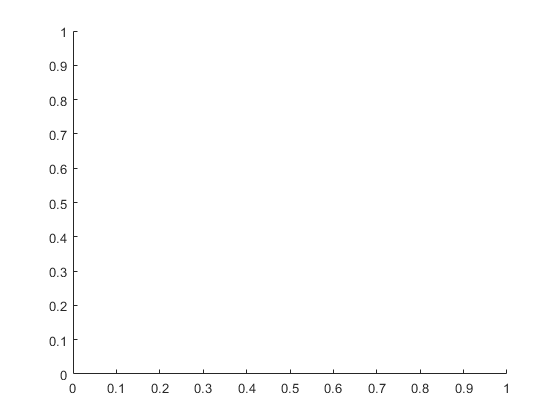

%plot(angles,avg_energy)
figure()
hold on

best_spiral = best_spiral.linear_extend(pi/6,50); %adding extension of the pulley

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

Error in spiral/linear_extend (line 109)
            obj.r = [ones(length(th_extend),1)*obj.r1,obj.r]; %adding aditional radius

best_spiral.theta
plot(angles,avg_energy_sqr)
best_spiral.plot_all(n_steps,best_spiral.spring_offset-10)


## Optimizing Constant force pulley

%setting up the optimization for the outer radius
optimizationrange = 1*r2;
r2_min = r2 - 5

r2_min = 22.6000

r2_max = r2 + optimizationrange;
r_stepsize = (r2_max - r2_min)/50

r_stepsize = 0.6520

r2_optimize = [r2_min:r_stepsize:r2_max]

r2_optimize =    22.6000   23.2520   23.9040   24.5560   25.2080   25.8600   26.5120   27.1640   27.8160   28.4680   29.1200   29.7720   30.4240   31.0760   31.7280   32.3800   33.0320   33.6840   34.3360   34.9880   35.6400   36.2920   36.9440   37.5960   38.2480   38.9000   39.5520   40.2040   40.8560   41.5080   42.1600   42.8120   43.4640   44.1160   44.7680   45.4200   46.0720   46.7240   47.3760   48.0280   48.6800   49.3320   49.9840   50.6360   51.2880   51.9400   52.5920   53.2440   53.8960   54.5480



clear best_spiral %clearing the best spiral object
lowest_avg = Inf; %setting the lowest average to infinity
avg_energy_sqr = zeros(1,length(angles));

for j = 1 : length(offsets)
    for i = 1: length(r2_optimize)
        cf_spiral = basic_spiral;
        cf_spiral.r2 =  r2_optimize(i); %setting the optimization radius 
        cf_spiral = cf_spiral.Spiral_constant_Force(n_steps); %creating spiral shape
        cf_spiral = cf_spiral.complete_analysis(n_steps,offsets(j)); %performing the analysis
        avg_energy_sqr(i) = mean((cf_spiral.Etot).^2);  %computing the absolute average energy 
        %taking the square to take into account negative energy values and
        %punnishing higher deviation from 0
        if avg_energy_sqr(i) <= lowest_avg
            if sum(cf_spiral.Fres <= 0) == 0 %Fres < 0 is underisrable as the mass will drop
                %checking if the current average potential energy is lower than the
                %current best
                lowest_avg = avg_energy_sqr(i);
                best_spiral = cf_spiral; %setting the new best potential energy 
            
            end
        end
    end
end

## Plotting the results

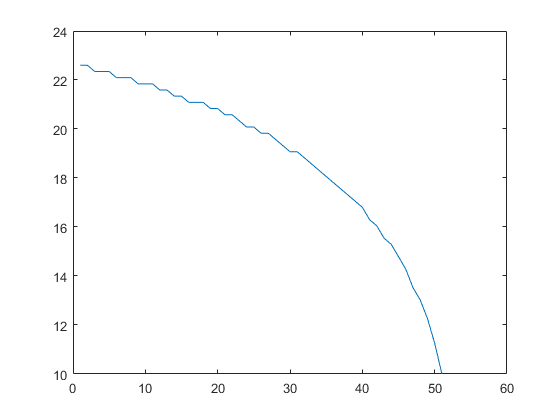

plot(best_spiral.rs)

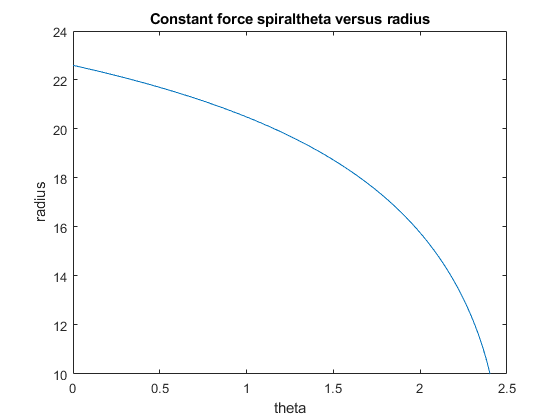

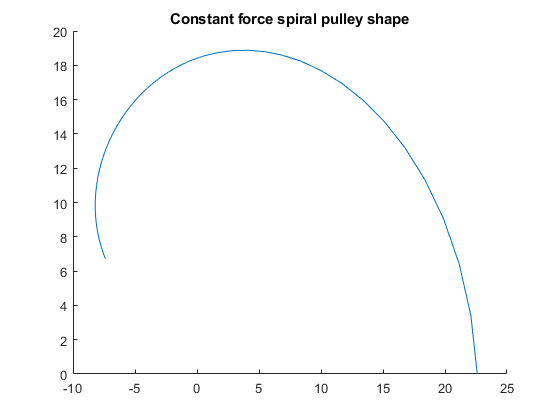

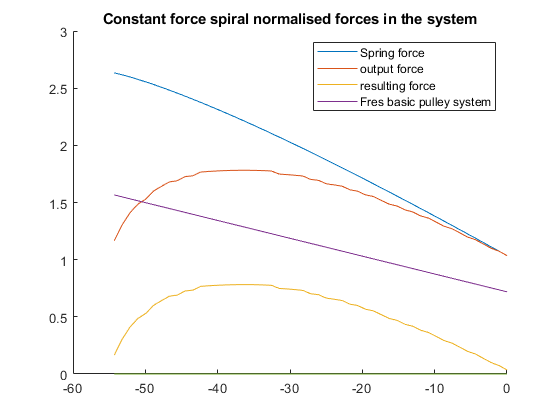

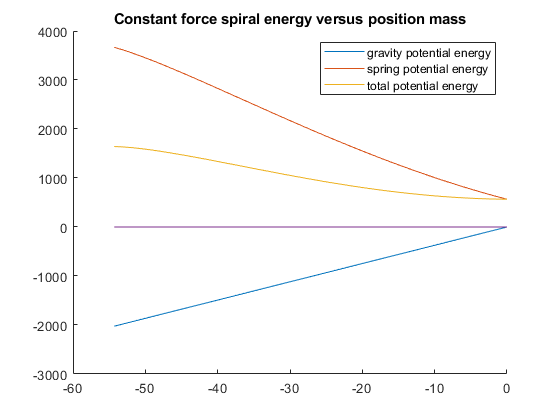

ans =   spiral with properties:

                   r1: 10
                   r2: 22.6000
                   F0: 37.2780
                    k: 1.3150
                 name: 'Constant force spiral'
                    S: 640.6713
                    r: [1×51 double]
                theta: [1×51 double]
                    x: [1×51 double]
                    y: [1×51 double]
    spiral_max_stroke: 54.2965
          curve_angle: []
                 x_m2: 54.2965
                  x_m: [1×51 double]
                  x_s: [1×51 double]
                   rs: [1×51 double]
                  phi: [1×51 double]
        spring_offset: 1
                   Fm: [1×51 double]
                   Fs: [1×51 double]
                 Fres: [1×51 double]
           Fm_control: [1×51 double]
                   Eg: [1×51 double]
                   Es: [1×51 double]
                 Etot: [1×51 double]


%ylim([-1 100000])
best_spiral.plot_all(n_steps,best_spiral.spring_offset)

## Optimizing Archimedes pulley

%setting up the optimization for the outer radius
optimizationrange = 2*r2;
r2_min = r2 - 5

r2_min = 22.6000

r2_max = r2 + optimizationrange;
r_stepsize = (r2_max - r2_min)/50

r_stepsize = 1.2040

r2_optimize = [r2_min:r_stepsize:r2_max]

r2_optimize =    22.6000   23.8040   25.0080   26.2120   27.4160   28.6200   29.8240   31.0280   32.2320   33.4360   34.6400   35.8440   37.0480   38.2520   39.4560   40.6600   41.8640   43.0680   44.2720   45.4760   46.6800   47.8840   49.0880   50.2920   51.4960   52.7000   53.9040   55.1080   56.3120   57.5160   58.7200   59.9240   61.1280   62.3320   63.5360   64.7400   65.9440   67.1480   68.3520   69.5560   70.7600   71.9640   73.1680   74.3720   75.5760   76.7800   77.9840   79.1880   80.3920   81.5960



clear best_spiral %clearing the best spiral object
lowest_avg = Inf; %setting the lowest average to infinity
avg_energy_sqr = zeros(1,length(angles));

for j = 1 : length(offsets)
    for i = 1: length(r2_optimize)
        archimedes_spiral = basic_spiral;
        archimedes_spiral.r2 =  r2_optimize(i); %setting the optimization radius 
        archimedes_spiral = archimedes_spiral.archimedes(n_steps,theta_max); %creating spiral shape
        archimedes_spiral = archimedes_spiral.complete_analysis(n_steps,offsets(j)); %performing the analysis
        avg_energy_sqr(i) = mean((archimedes_spiral.Etot).^2);  %computing the absolute average energy 
        %taking the square to take into account negative energy values and
        %punnishing higher deviation from 0
        if avg_energy_sqr(i) <= lowest_avg
                            lowest_avg = avg_energy_sqr(i);
                best_spiral = archimedes_spiral; %setting the new best potential energy 
            if sum(archimedes_spiral.Fres <= 0) == 100090 %Fres < 0 is underisrable as the mass will drop
                %checking if the current average potential energy is lower than the
                %current best

            end
        end
    end
end

## Plotting the results

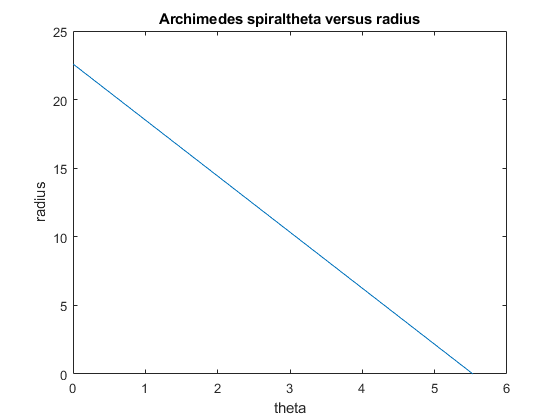

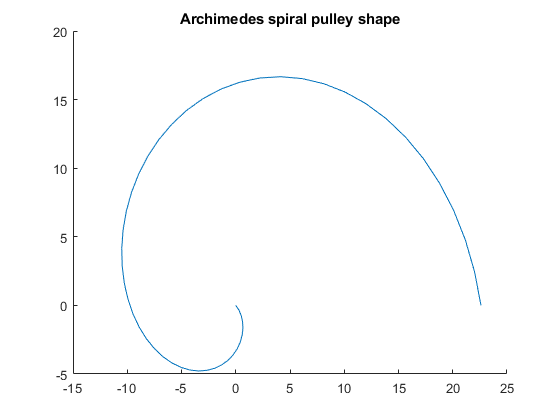

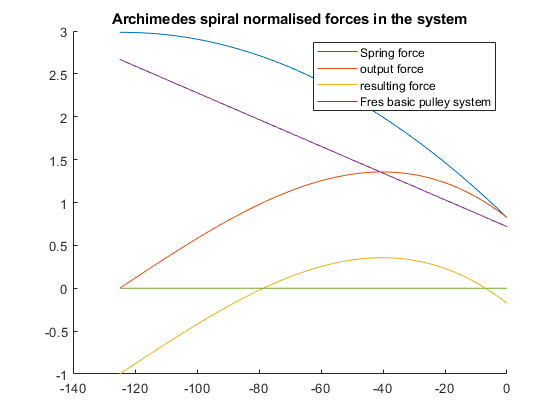

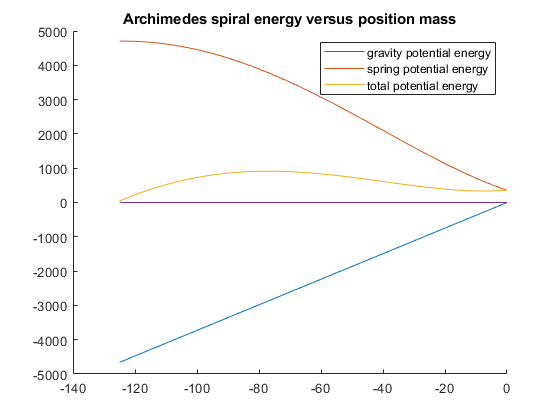

ans =   spiral with properties:

                   r1: 10
                   r2: 22.6000
                   F0: 37.2780
                    k: 1.3150
                 name: 'Archimedes spiral'
                    S: []
                    r: [1×51 double]
                theta: [1×51 double]
                    x: [1×51 double]
                    y: [1×51 double]
    spiral_max_stroke: 124.9600
          curve_angle: []
                 x_m2: 124.9600
                  x_m: [1×51 double]
                  x_s: [1×51 double]
                   rs: [1×51 double]
                  phi: [1×51 double]
        spring_offset: -5
                   Fm: [1×51 double]
                   Fs: [1×51 double]
                 Fres: [1×51 double]
           Fm_control: [1×51 double]
                   Eg: [1×51 double]
                   Es: [1×51 double]
                 Etot: [1×51 double]



%ylim([-1 100000])
best_spiral.plot_all(n_steps,best_spiral.spring_offset)